# The HDF5/HTM large catalog format,catsHTM directory and access functions in the MATLAB and Python

## Description

The HDF5/HTM format designed to store and provide fast access for large astronomical catalogs with >10^6 rows. The format is based on the HDF5 file format and HDF5 file access utilities which are available on many platforms. The catalog format is designed to allow fast access for cone searches in the range of 1 arcsec to about 1 deg. For fast access, the sources are sorted into [hierarchical triangular mesh](https://arxiv.org/pdf/cs/0701164.pdf) (HTM). 

Several tools for creating and accessing the HDF5/HTM files are provided. Using the matlab tools, the typical search and retrival time for a 10 arcsec cone search is about 2-4 milliseconds (almost independent of the number of sources in the catalog).

## Python version

Python version is available from [github](https://github.com/maayane/catsHTM).

The Python version has only a cone search capabilities.

## Available catalogs

See list in [http://euler1.weizmann.ac.il/catsHTM/](http://euler1.weizmann.ac.il/catsHTM/)

Note that the catalog base name used in the access program may be different than the catalog name.

## Credit

[See catsHTM credit page](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/catsHTMcredit.html).

## License

Unless specified otherwise this code and products are released under the GNU general public license version 3.

## Installation

**Python**

The Python code is available from [github](https://github.com/maayane/catsHTM).

**MATLAB**

`catsHTM` is distributed as part of the MATLAB Astronomy & Astrophysics Toolbox. See[ http://weizmann.ac.il/home/eofek/matlab/doc/install.html ](http://webhome.weizmann.ac.il/home/eofek/matlab/doc/install.html)for installation instruction and additional documentation.

**Catalogs download**

The `catsHTM` directory is very large and therefore available on request. After copying the data you need to add the directories path to your startup.m file.

The HDF5/HTM catalogs requires about 2.1TB of disk space.

Data is available from:

- Web download - See instructions in: [http://euler1.weizmann.ac.il/catsHTM/](http://euler1.weizmann.ac.il/catsHTM/)

- Shared (and updated automatically) via Dropbox on request from eran dot ofek at weizmann dot ac dot il.

# Structure and methodlogy

The data of each catalog is partitioned in the following way. We divide the celestial sphere using a Hierarchical Triangular Mesh (HTM) quad-tree ([Szalay et al. 2005](https://arxiv.org/pdf/cs/0701164.pdf)). This method is based on a recursive subdivision of the celestial sphere into spherical triangles of similar shapes, called ``trixels''. The HTM method of dividing the sphere is particularly good at supporting searches at a wide range of resolutions (hemispheres to arc seconds). In our case, depending on the size of the catalog, the ``level'' of the HTM (i.e. the number of subdivisions necessary to create the smallest trixel) varies between 6 and 9.

The reason why we do~not use higher levels is that having the data stored continuously in memory improves the efficiency of the search. The amount of levels we chose ensures good efficiency for cone searches at resolutions spanning from a few arc-seconds to a few degrees, i.e. the typical resolutions usually used for astronomical applications. Each trixel in the quad-tree is allocated a number, which is referred to as the trixel ``index'' throughout this paper.

To store the data of the partitioned catalogs, we use datasets, one of the object types available within the HDF5 data model. A dataset is simply a multidimensional arrays and a HDF5 file can contain multiple datasets. 

For each trixel, we created a pair of datasets: 

- The``trixel-dataset", containing data (if the trixel belongs to the highest level in the tree, then the data it contains is the actual catalog data for all the sources in the trixel, sorted by declination. Otherwise the datasets does not exist.

- The``index-dataset'', containing the line number and declination of the sources contained in the trixel, in steps of 30-300 lines. This second dataset can be used, in some cases, to expedite a search within a trixel.

These pairs of datasets were then stored, in groups of 100 (by default), in HDF5 files.

For each partitioned catalog, We created an additional HDF5 file, called the ``HDF5 index file'' (named: <CatName>_htm.hdf5), which contains one dataset ("<CatName>_HTM") with the information needed in order to access the relevant trixels, when making a cone search. The HDF5 index file contains as many lines as trixels in the tree. Each line corresponds to one trixel and contains: the index of the trixel; the indexes of the adjacent trixels; the sky coordinates (latitude and longitude) of the trixel; the number of sources it contains ({\tt NaN} if the trixel does not belong to the highest level in the tree). The HDF5 index file allows to perform an easy search for all the trixels that intersect a given cone.

Finally, we also keep a file containing additional meta data, such as the catalog column names and units.

## Notes

The datasets that contain the catalogs are named "htm_%06d", where %06d is the format of the HTM index. These indices are generated by the `celestial.htm.htm_build` function. 

The dataset index file is named "htm_%06d_Ind".

The HTM index file matrix contains the following 13 columns:

- Level - The HTM level (first level is 0).

- Father - The HTM index (line number) of the HTM father.

- Son1 - The HTM index of the 1st son of the HTM. The sons of the final HTM (in which data is actually stored) are NaNs.

- Son2 - The HTM index of the 2nd son of the HTM.

- Son3 - The HTM index of the 3rd son of the HTM.

- Son4 - The HTM index of the 4th son of the HTM.

- Pole1 Long - Longitude (J2000 R.A.) of the pole of the first arc of the HTM.

- Pole1 Lat - Latitude  (J2000 Dec.) of the pole of the first arc of the HTM.

- Pole2 Long - Longitude (J2000 R.A.) of the pole of the 2nd arc of the HTM.

- Pole2 Lat - Latitude  (J2000 Dec.) of the pole of the 2nd arc of the HTM.

- Pole3 Long - Longitude (J2000 R.A.) of the pole of the 3rd arc of the HTM.

- Pole3 Lat - Latitude  (J2000 Dec.) of the pole of the 3rd arc of the HTM.

- Nsrc - Number of sources in HTM dataset. NaN or 0, if HTM dataset doesn't exist

Finally, the catalog column names and units are stored in a mat file named: "<CatName>_htmColCell.mat". The column names and units are stored in cell array named ColCell and ColUnits, respectively.

## Example

The data/catsHTM/FIRST/ directory contains 153 files. The names of 151 of the files  are <CatName>_htm_%06d.hdf5, where CatName is the catalog name (e.g., 'FIRST'). Each file contains up to 100 datasets, named "htm_%06d", that contain all the sources in a specific HTM of level 7. For each dataset, there is an index dataset named "htm_%06d_Ind". Example:

Info=h5info('GAIADR1_htm_021500.hdf5');
% There are 200 datasets (100 pairs of data + ind)
Info.Datasets

ans =   200×1 struct array with fields:

    Name
    Datatype
    Dataspace
    ChunkSize
    FillValue
    Filters
    Attributes


Info.Datasets(1)

ans =           Name: 'htm_021500'
      Datatype: [1×1 struct]
     Dataspace: [1×1 struct]
     ChunkSize: []
     FillValue: 0
       Filters: []
    Attributes: [2×1 struct]


Info.Datasets(2)

ans =           Name: 'htm_021500_Ind'
      Datatype: [1×1 struct]
     Dataspace: [1×1 struct]
     ChunkSize: []
     FillValue: 0
       Filters: []
    Attributes: []


ans =         2722           8


ans =         2722           8


ans =         2722           8


ans =         2722           8


# Search the catalogs

## Cone searches

The catalogs are optimized for cone searches. The basic low-level function for searching the catalogs is `catsHTM.cone_search`. The arguments of this function are: catalog name, J2000 R.A. in radians, J2000 Dec. in radians, search radius in arcsec, and optional pairs of keyword values.

[Cat,ColCell]=catsHTM.cone_search('APASS',1,1,100)

Cat =       0.99972            1        0.711        0.518   2.0122e+07            2           10       15.358        0.876       16.234       15.717       14.776       14.329            0        0.054        0.054        0.029        0.071        0.053


ColCell =     'RA'    'Dec'    'RAerr'    'Decerr'    'Name'    'Nobs'    'Mobs'    'V'    'BV'    'B'    'g'    'r'    'i'    'Verr'    'BVerr'    'Berr'    'gerr'    'rerr'    'ierr'


[Cat,ColCell]=catsHTM.cone_search('GAIADR1',1,1,10,'OutType','astcat')

Cat =   AstCat with properties:

            Cat: [0×8 double]
            Col: [1×1 struct]
        ColCell: {'RA'  'Dec'  'ErrRA'  'ErrDec'  'MagG'  'ErrMagG'  'ExcessNoise'  'ExcessNoiseSig'}
       ColUnits: []
       SortedBy: []
    SortedByCol: []
           Name: []
         Source: []
      Reference: []
        Version: []
         Header: {0×3 cell}
            WCS: []
       UserData: []


ColCell =     'RA'    'Dec'    'ErrRA'    'ErrDec'    'MagG'    'ErrMagG'    'ExcessNoise'    'ExcessNoiseSig'


Additional high and low level functions to access these catalogs as well as other online and offline catalog is available in the [VO package](https://webhome.weizmann.ac.il/home/eofek/matlab/doc/VO.html).

Specifically, the `VO.search.cat_cone` function can search for catalogs in the `catsHTM` format as well as all the catalogs in the `+cats` package.

## Serial searches

You can perform serial search with that execute a function on the entire catalog and optionaly save the results. The following example, execute the command `sin` on the entire APASS catalog. Note that by default this will run on multiple (24) processors, but you can specify the number of parallel processors using the 'NparPool' keyword.

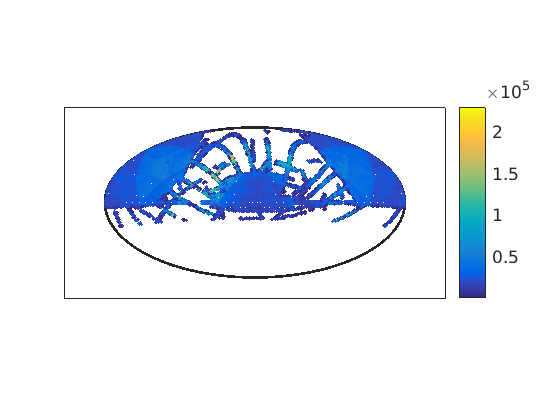

[ColCell]=catsHTM.serial_search('APASS',@sin)

## Cross match the catalogs

You can cross match two catalogs and execute a function on the output. For example, the following command will cross match the entire APASS catalog with the 2MASS catalog:

catsHTM.xmatch_2cats('APASS','TMASS')

# Reading specific HTM tiles

We can read one of these datasets - these can be done using several functions. First, using the built in MATLAB function:

Data=h5read('GAIADR1_htm_021500.hdf5','/htm_021502');
size(Data)

or using functions in te HDF5 static class:

Data=HDF5.load('GAIADR1_htm_021500.hdf5','htm_021502');
size(Data)


or using the functions in the catsHTM static class:

Data = catsHTM.load_cat('GAIADR1_htm_021500.hdf5','htm_021502');
size(Data)

However, you can also use the more convinient style:

Data = catsHTM.load_cat('GAIADR1',21502);
size(Data)

# Additional functions

There are several low level functions for accessing and generating the catalogs, constructing the file and dataset names, and catalog statistics and display.

- `catsHTM.filename2base` - Convert HDF5/HTM file name to catalog name (file base name).

- `catsHTM.get_file_var_from_htmid` - Construct file and var name for HTM file stored in HDF5.

- `catsHTM.get_index_filename` - Get HDF5/HTM index file name and variable name from CatName.

- `catsHTM.save_cat` - save catalog data in HDF5 file.

- `catsHTM.save_htm_ind` - Save HTM indinces of the celestial sphere in an HDF5 file.

- `catsHTM.save_cat_colcell `- Save ColCell cell array of an HTM catalog

- `catsHTM.load_cat` - Load catalog stored in an HDF5 file.

- `catsHTM.load_multiple_cats` - Load HDF5/HTM catalog from multiple files/datasets

- `catsHTM.load_colcell` - Load ColCell and ColUnits for an HDF5/HTM catalog

- `catsHTM.load_htm_ind` - load HTM data into structure from an HDF5 file

- `catsHTM.search_htm_ind` - A coordinate cone search in an HTM stored in HDF5 file.

- `catsHTM.htm_search_cone` - Search for all HTM leafs interscting a small circle (cone search)

- `catsHTM.get_nsrc` - Count number of sources over all HTM in HDF5 files

- `catsHTM.nsrc` - Count sources in the HDF5/HTM index file

# Plot functions

You can plot the sky surface density in a catalog using the `catsHTM.plot_density` command.

% plot the SDSS/DR10 source density per deg^2
% see help catsHTM.plot_density for additional options
catsHTM.plot_density('SDSSDR10');